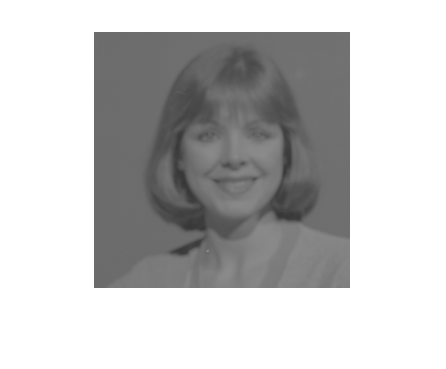

img1=imread("wom1.PNG");
imshow("wom1.PNG")

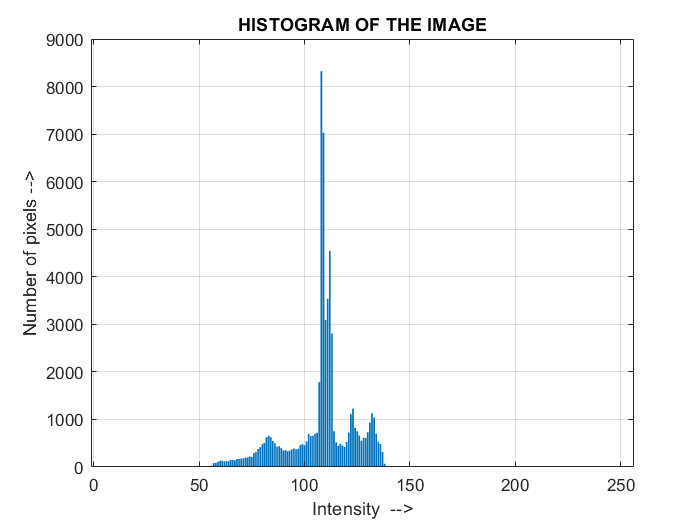


histo(img1)

img2=imread("wom1.PNG");
imshow("wom1.PNG");

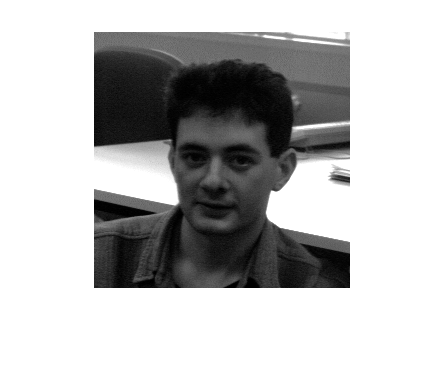


img3=imread("man8.png");
imshow("man8.png");

   144

   55



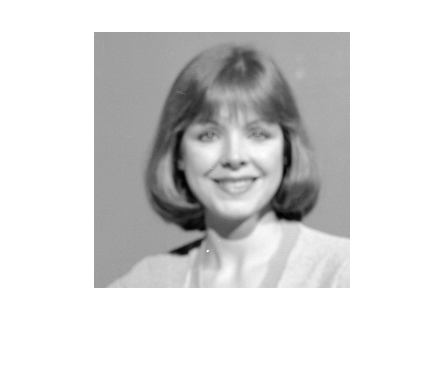

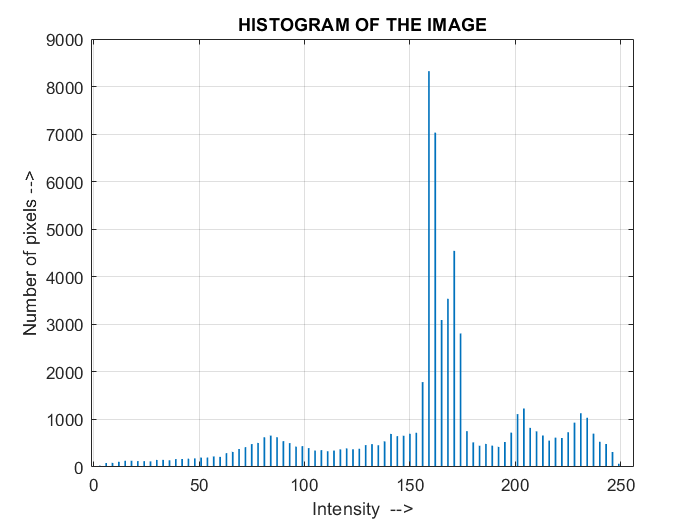


ContrastSterch(img2);

   158

   0



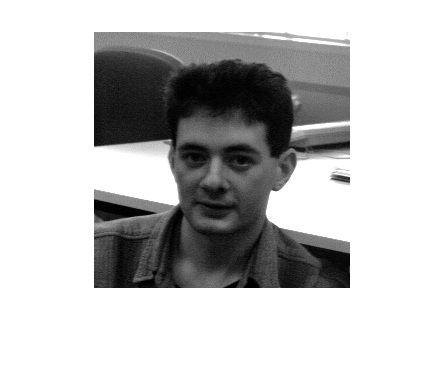

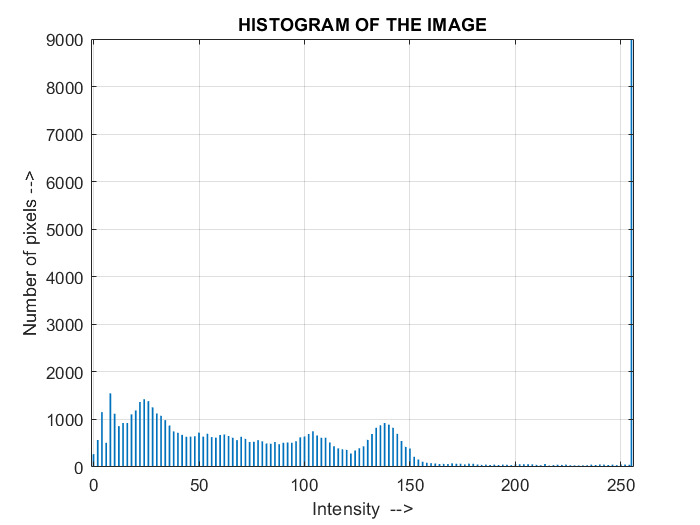

%histo(img2)
ContrastSterch(img3);

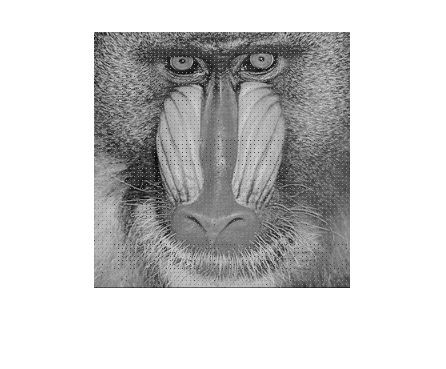

A=imread("mbaboon.bmp");
imshow("mbaboon.bmp");


%B= blockproc(A,[4 4],fun)
%Y= fun(BLOCK_Struct)

%fun=@(block_struct) imresize(block_struct.data,0.5);
%B= blockproc(A,[4 4],fun);
%C= blockproc(B,[2 2],fun);
%D= blockproc(B,[1 1],fun);
%imshow(B)
%imshow(C)
%imshow(D)

%fun2=@(block_struct) imresize(block_struct.data,0.25);
%B1= blockproc(A,[4 4],fun2);
%C1= blockproc(B,[2 2],fun2);
%imshow(C1)

B= blockproc(A,[4 4],@(block_struct) block_struct.data(4,4));

disp("4*4")

4*4


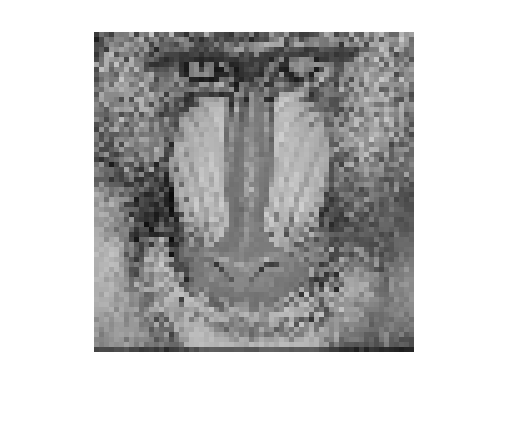

imshow(B,"InitialMagnification",500)

C= blockproc(A,[4 4],@(block_struct) block_struct.data(2,2));
disp("2*2")

2*2


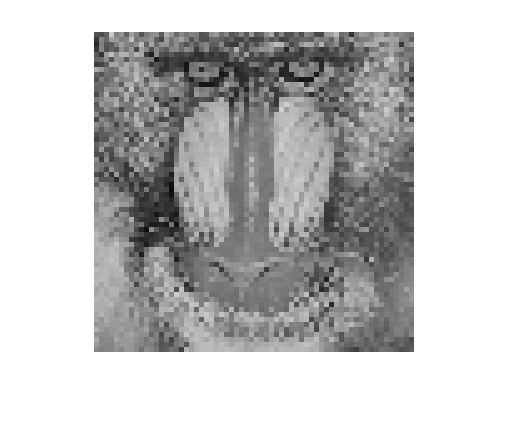

imshow(C,"InitialMagnification",500)

D= blockproc(A,[4 4],@(block_struct) block_struct.data(1,1));
disp("1*1")

1*1


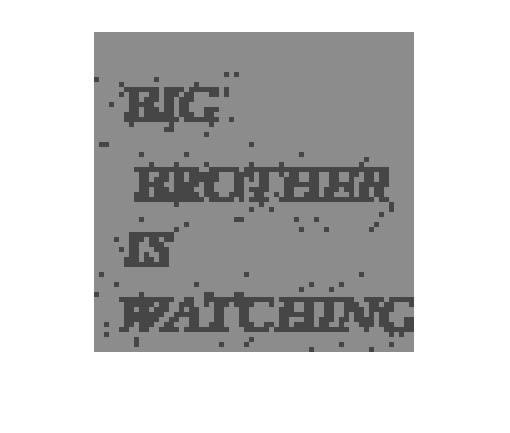

imshow(D,"InitialMagnification",500)


E= blockproc(A,[4 4],@(block_struct) uint8(mean(block_struct.data(:))));
disp("Mean")

Mean


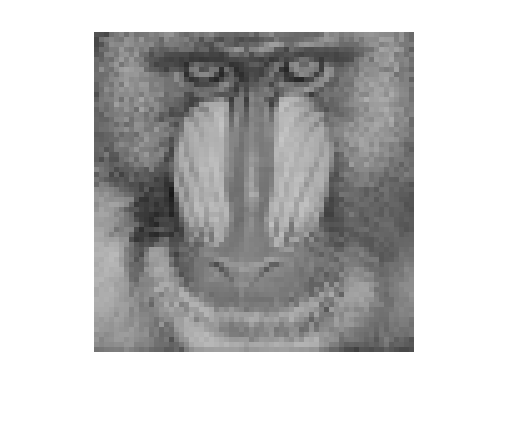

imshow(E,"InitialMagnification",500)

%help blockproc

Task 3

Dark adaptation

Task 4

I1=imread("mbaboon.bmp");
imshow("mbaboon.bmp");

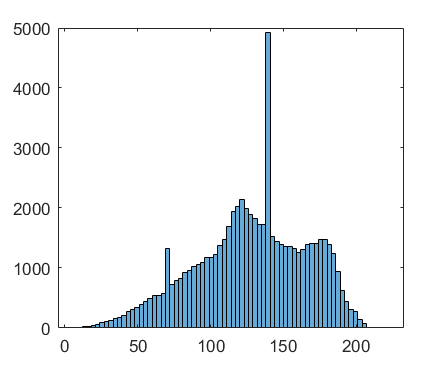

g1 = I1 + 10;
max(0, g1);
min(255, g1);
g2 = I1 .* 1.1;
max(0, g2);
min(255, g2);
g3 = imrotate(I1,-90);
h1 = histogram(I1);

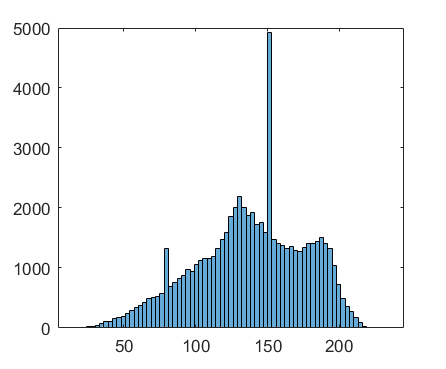

hf1 = histogram(g1);

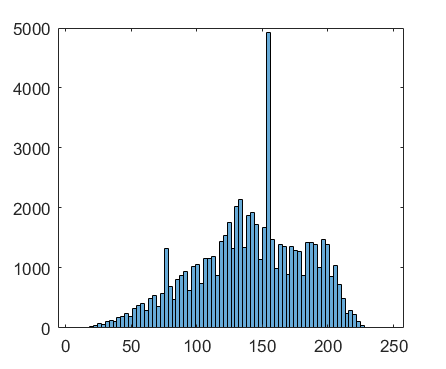

hf2 = histogram(g2);

hf3 = histogram(g3);

function ContrastSterch(img)
[x, y] = size(img);
Imin=300;
Imax=0;

for j = 1 : x
        for k = 1 : y
            if img(j, k) < Imin
                Imin= img(j, k);
            end
            if img(j, k) > Imax
                Imax= img(j, k);
            end
        end
end

disp(Imax);
disp(Imin);
newMin=0;
newMax=255;
for j = 1 : x
        for k = 1 : y
            I=img(j, k);
            Inew=((I-Imin)*((newMax-newMin)/(Imax-Imin)))+newMin;
            img(j, k)=Inew;
        end
end
figure()
imshow(img)


histo(img)
end


function histo(img)

[x, y] = size(img);
frequency = 1 : 256;
  
count = 0;
for i = 1 : 256
    for j = 1 : x
        for k = 1 : y
            if img(j, k) == i-1
                    count = count + 1;
            end
        end
    end
    frequency(i) = count;
    count = 0;
end 
n = 0 : 255;
figure()
bar(n, frequency);
grid on;
ylabel('Number of pixels -->');
xlabel('Intensity  -->');
title('HISTOGRAM OF THE IMAGE');
end